# FITNESS TRACKER: Counting Steps, Creating Graphics, Classifying Activity

## Counting Steps

### 1. Preparing Data

To work with the data, we must first load it into the workspace and store the variables that are going to be used in this example. While we can double click on the data to load it, we will use the [`load`](https://www.mathworks.com/help/matlab/ref/load.html) command to make this process easier to replicate.

clear
load('walk.mat');
lat=Position.latitude;
lon=Position.longitude;
positionDatetime=Position.Timestamp;

Xacc = Acceleration.X;
Yacc = Acceleration.Y;
Zacc = Acceleration.Z;
accelDatetime=Acceleration.Timestamp;

% We use the following to obtain linear time data in seconds from a datetime array
positionTime=timeElapsed(positionDatetime);
accelTime=timeElapsed(accelDatetime);

### 2. Determining Approach Method

Let’s say that you wanted to track the number of steps taken. One way that this can be done is by calculating the total distance traveled and then dividing it by your stride length. This works because stride is the distance taken for one step so if we look at the units they cancel out as seen below.

     
$$\frac{\textrm{totalDistance}\left(\textrm{ft}\right)}{\textrm{stride}\left(\frac{\textrm{ft}}{\textrm{step}}\right)}=\frac{\textrm{ft}}{\frac{\textrm{ft}}{\textrm{step}}}=\textrm{ft}*\frac{\textrm{step}}{\textrm{ft}}=\textrm{steps}$$


Now that we have an equation, the next step is to solve it in MATLAB. First, we need to get the total distance traveled, which is done using data from your GPS location or the latitude and longitude sensor data. One way that we can calculate this is by looking at your start location and end location and calculating the distance between those points. If we did that with the figure below, the distance traveled would be 300ft because the start and end position is 3 squares apart. 

 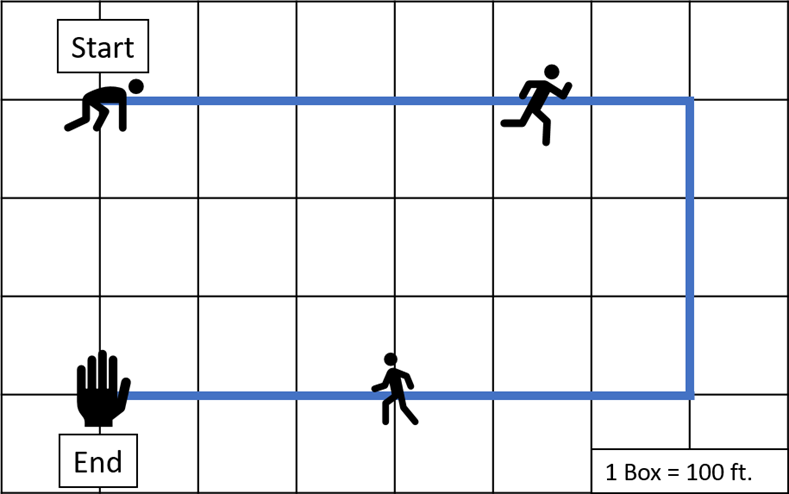

We can see that the person traveled much further than this, so we must calculate the distance along the path using **each data point**. Now we can accurately calculate that the person traveled 1500ft, which is a large difference from the 300ft originally calculated. 

Once we have an accurate measure of distance, we can divide this by average stride length to calculate number of steps taken!

### 3. Coding The Model

In this example, latitude and longitude have been stored into variable names *lat* and *lon* respectively. The first step in using these to calculate distance is to declare a couple of variables: one will represent the circumference of the earth in miles, the other will represent the total distance traveled, which will be set to zero for now.

earthCirc = 24901;
totaldis = 0;
 totaldis

totaldis = 0

To solve this problem, calculations will have to be repeated several times in a loop. Because of this, we use a function called a [`for loop`](https://www.mathworks.com/help/matlab/ref/for.html) which will repeat a block of code *for* a specified number of times. In this case, we want to have it run until the end of our vector of data. The [`length`](https://www.mathworks.com/help/matlab/ref/length.html) command can be used to determine the number of elements in a vector and therefore how many times we need to run the loop. When solving for the difference in position, one position and the next position are used at the same time, so we need to stop one before the end of the vector as seen below. If this isn't done, we will get an error because we will be trying to acces data from outside of the vector.

for i = 1:(length(lat)-1)
     

Now we save the first position and the second position into variables. We will do this using the variable *i* from above. This variable is a vector from 1 to the end of our latitude vector which can be used to index the latitude and longitude vectors.

    lat1 = lat(i);     % The first latitude
    lat2 = lat(i+1);   % The second latitude
    lon1 = lon(i);     % The first longitude
    lon2 = lon(i+1);   % The second longitude

Thankfully for us, MATLAB has a command [`distance`](https://www.mathworks.com/help/map/ref/distance.html) that calculates distance when given latitude and longitude. This will give us the difference in degrees which we will then turn into length by creating equivalent fractions:


$$\frac{\textrm{traveledDistance}}{\textrm{earth'sCircumference}}=\frac{\textrm{degreesTraveled}}{\textrm{earth'sDegrees}}\;$$


From this we solve for 'traveledDistance'. We will use 360 for 'earth’sDegrees' because that is the total number of degrees in a circle. While the earth is not a perfect circle, this will still be a good estimation

    degDis = distance(lat1, lon1, lat2, lon2);
    dis = (degDis/360)*earthCirc;

Now we add up the distance and store it into the *totaldis* variable. What this code will do is take the previous total distance and add the distance just calculated onto it. With this, we have calculated everything that we needed to within the for loop and must close the loop by using the [`end`](https://www.mathworks.com/help/matlab/ref/end.html) command.

    totaldis = totaldis + dis;
end

Once the for loop has finished, we will have the total distance traveled! From here, we need to divide the total distance traveled by the stride to get the steps taken. For this example, we will use the average stride of 2.5ft. Since *totaldis* is the total distance traveled in miles, we will have to convert this into feet before we can divide it by the stride. 

stride = 2.5;                   % Average stride (ft)
totaldis_ft = totaldis*5280;    % Converting distance from miles to feet
steps = totaldis_ft/stride;
steps

steps = 1.1233e+03

An easy way to see the data that you are interested in is by priniting it to the screen once you find it. While you could also show it by removing the semicolon, the [`disp`](https://www.mathworks.com/help/matlab/ref/disp.html) command allows you to add text as well to specify exactly what data you are looking at.

disp(['The total distance traveled is: ', num2str(totaldis),' miles'])

The total distance traveled is: 0.53186 miles


disp(['You took ', num2str(steps) ' steps'])

You took 1123.2849 steps


### **CREATING GRAPHICS**

plot(accelTime,Xacc);

Unrecognized function or variable 'accelTime'.

hold on;
plot(accelTime,Yacc); 
plot(accelTime,Zacc);
xlim([0 50])
legend('X Acceleration','Y Acceleration','Z Aceeleration');
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)');
title('Acceleration Data Vs. Time');
hold off

## Classifying Activity

In addition to counting steps, let's say that you want to know what kind of activity you were doing. Let's train a machine learning model that takes a person's acceleration data and shows if they were sitting, walking, or running.

### 1. Prepare the data

First, you'll need to collect sensor data for each of these activities. For simplicity, I collected this data in three different sessions: one where I was sitting the whole time ('sitAcceleration'), one where I was walking ('walkAcceleration'), and one where I was running ('runAcceleration'). This is just a sample dataset, and you may wish to collect more data when training your own model for higher accuracy. 

Let's load the logs for these sessions and preview one of them to get a sense of how the data is structured.

load allacceleration.mat
head(sitAcceleration) 

           Timestamp               X          Y         Z   
    ________________________    _______    _______    ______

    20-Jun-2024 16:40:48.985    0.50131    0.40835    9.6401
    20-Jun-2024 16:40:49.085    0.51777    0.38395    9.7335
    20-Jun-2024 16:40:49.184    0.52391    0.38455    9.7289
    20-Jun-2024 16:40:49.284    0.52316    0.39024    9.7052
    20-Jun-2024 16:40:49.384      0.529     0.3862    9.7161
    20-Jun-2024 16:40:49.483    0.50909    0.38964    9.7109
    20-Jun-2024 16:40:49.583     0.5272    0.39129     9.731
    20-Jun-2024 16:40:49.683    0.54232    0.37003      9.76



Now we need to add the activity labels to each table.

sitLabel = 'sitting';
sitLabel = repmat(sitLabel, size(sitAcceleration, 1), 1);
sitAcceleration.Activity = sitLabel

sitAcceleration = 6023×4 timetable
           Timestamp               X          Y         Z       Activity
    ________________________    _______    _______    ______    ________

    20-Jun-2024 16:40:48.985    0.50131    0.40835    9.6401    sitting 
    20-Jun-2024 16:40:49.085    0.51777    0.38395    9.7335    sitting 
    20-Jun-2024 16:40:49.184    0.52391    0.38455    9.7289    sitting 
    20-Jun-2024 16:40:49.284    0.52316    0.39024    9.7052    sitting 
    20-Jun-2024 16:40:49.384      0.529     0.3862    9.7161    sitting 
    20-Jun-2024 16:40:49.483    0.50909    0.38964    9.7109    sitting 
    20-Jun-2024 16:40:49.583     0.5272    0.39129     9.731    sitting 
    20-Jun



% Add 'Activity' labels to each dataset
% Ensure labels are in cell arrays to maintain consistency across tables

% For sitting data
sitLabel = repmat({'sitting'}, size(sitAcceleration, 1), 1);
sitAcceleration.Activity = sitLabel;

% For walking data
walkLabel = repmat({'walking'}, size(walkAcceleration, 1), 1);
walkAcceleration.Activity = walkLabel;

% For running data
runLabel = repmat({'running'}, size(runAcceleration, 1), 1);
runAcceleration.Activity = runLabel;

% For downstairs data
downLabel = repmat({'downstairs'}, size(downAcceleration, 1), 1);
downAcceleration.Activity = downLabel;

% For upstairs data
upLabel = repmat({'upstairs'}, size(upAcceleration, 1), 1);
upAcceleration.Activity = upLabel;



% Vertically concatenate all tables
allAcceleration = [sitAcceleration; walkAcceleration; runAcceleration; downAcceleration; upAcceleration];




Then we should combine all of our data into one table.

Last, we can remove the 'Timestamp' variable, since this variable does not help determine what type of activity we are doing.

allAcceleration = timetable2table(allAcceleration, "ConvertRowTimes", false)

allAcceleration = 83143×4 table
       X          Y         Z        Activity  
    _______    _______    ______    ___________

    0.50131    0.40835    9.6401    {'sitting'}
    0.51777    0.38395    9.7335    {'sitting'}
    0.52391    0.38455    9.7289    {'sitting'}
    0.52316    0.39024    9.7052    {'sitting'}
      0.529     0.3862    9.7161    {'sitting'}
    0.50909    0.38964    9.7109    {'sitting'}
     0.5272    0.39129     9.731    {'sitting'}
    0.54232    0.37003      9.76    {'sitting'}
    0.54726    0.35865    9.7367    {'sitting'}
    0.50939    0.32003    9.6474    {'sitting'}
    0.47766    0.31839    9.7277    {'sitting'}
      0.457    0.31285    9.7082    {'sitting'}
    0.42916    0.30342    9.7019    {'sitting'}
    0.43335    0.28261    9.6754    {'sitting'}
     0.4335    0.28546    9.7001    {'sitting'}
    0.43859    

### 2. Train a model

One way to train several different machine learning algorithms at once is to use the Classification Learner App, which allows you to rapidly prototype and fine tune your models until you have one you are happy with. You have a lot of options on how to use your data and train models in this app, so while this will be a basic workflow, you can learn more about the different options using this [documentation](https://www.mathworks.com/help/stats/classification-learner-app.html). 

First, open the app:

classificationLearner

### 3. Use the model

Now we can use that model to make predictions on new data! 'unknownAcceleration' (from ActivityLogs.mat, which we loaded earlier) is a log of acceleration data collected during a sample workout that included walking, running, and sitting, so we can use our machine learning model to predict what activity the person was doing for each timestamp. 

unknownAcceleration

unknownAcceleration = 3632×3 timetable
           Timestamp                X          Y         Z   
    ________________________    _________    ______    ______

    20-Jun-2024 20:09:37.795     -0.66537    3.4032    9.2059
    20-Jun-2024 20:09:37.894     -0.16885    3.4731    9.0717
    20-Jun-2024 20:09:37.994      -0.5293    3.4824    8.7201
    20-Jun-2024 20:09:38.094      -1.1159    3.1888    8.6845
    20-Jun-2024 20:09:38.194     -0.93525    3.2538    9.6229
    20-Jun-2024 20:09:38.293      -1.0435    3.9299    9.4365
    20-Jun-2024 20:09:38.393     -0.83257    3.8837    9.0373
    20-Jun-2024 20:09:38.493      -0.3585    3.9486    8.7986
    20-Jun-2024 20:09:38.592     -0.49263    4.2515

justAcc = timetable2table(unknownAcceleration, "ConvertRowTimes", false);
yfit = trainedModel.predictFcn(justAcc)

yfit = 3632×1 cell array
    {'walking'}
    {'walking'}
    {'walking'}
    {'walking'}
    {'walking'}
    {'running'}
    {'running'}
    {'running'}
    {'running'}
    {'running'}
    {'walking'}
    {'walking'}
    {'walking'}
    {'running'}
    {'running'}
    {'running'}
    {'running'}
    {'running'}
    {'running'}
    {'walking'}
    {'running'}
    {'walking'}
    {'running'}
    {'running'}
    {'running'}
    {'running'}
    {'running'}
    {'running'}
    {'running'}
    {'running'}


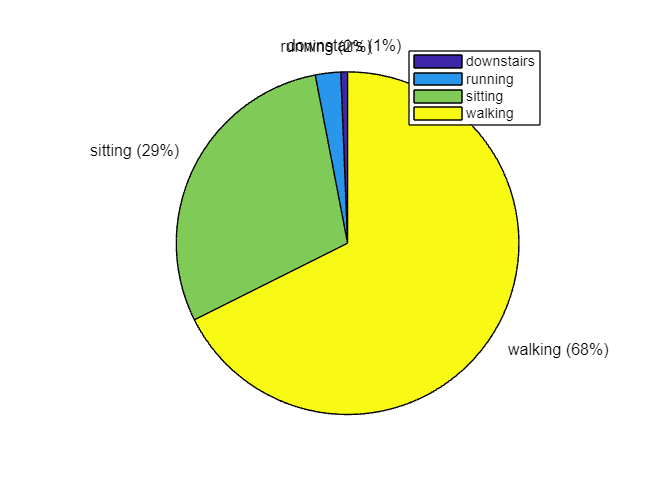

yfitcat = categorical(cellstr(yfit)); % convert to correct data type for histogram
pie(yfitcat)
legend(["downstairs", "running", "sitting", "walking"])